NP fix learning rate 

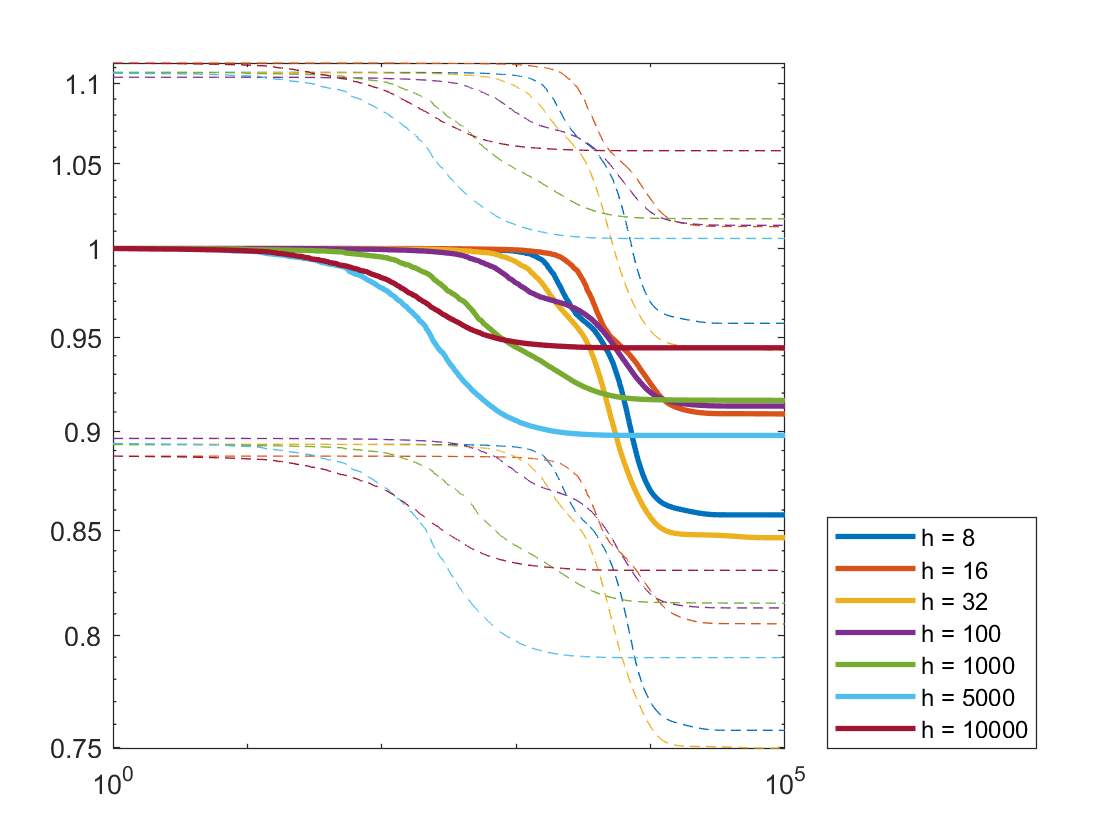

figure
n = 10;
m = 1;
iter = 100000;
num_run = 20;
h_M = [8 16 32 100 1000 5000 10000];
colors = [[0, 0.4470, 0.7410];[0.8500, 0.3250, 0.0980];[0.9290, 0.6940, 0.1250]; ...
    [0.4940, 0.1840, 0.5560];[0.4660, 0.6740, 0.1880];[0.3010, 0.7450, 0.9330];[0.6350, 0.0780, 0.1840]];
    %[0, 0, 1];[0, 0.5, 0];[1, 0, 0]];
p = zeros(1, length(h_M));
for k = 1:length(h_M)
h = h_M(k);
sigma = 0.01;
itanp = 10e-5;
etraj_all = zeros(num_run, iter);
for j = 1:num_run
%rng('default');
%rng(40);
wih_np = 0.01*normrnd(0,1,[h,n]);
%rng('default');
%rng(50);
who_np = 0.01*normrnd(0,1,[m,h]);
x = normrnd(0,1,[n,1]);
%fix target
rng('default');
rng(20+j);
w_star = normrnd(0,1/sqrt(n),[m,n]);
y_tar = w_star*x;
etraj = zeros(1,iter);
%etraj_2 = zeros(1,iter);
%eb = 0;
for i = 1:iter
% perturbation on hidden and output layers
enpo = normrnd(0,sigma,[m,1]);
enph = normrnd(0,sigma,[h,1]);
% without perturbation -> E
H = wih_np*x;
y = who_np*H;
e = 0.5*norm(y-y_tar)^2;
g_e = norm(who_np*wih_np-w_star)^2;
% with perturbation -> E_per
H_per = wih_np*x+enph;
y_per = who_np*H_per+enpo;
eper2 = 0.5*norm(y_per-y_tar)^2;
etraj(i) = g_e;
%etraj_2(i) = e;
% weights update 
deltawho_np = -(itanp/sigma^2)*(eper2-e)*enpo*H';
deltawih_np = -(itanp/sigma^2)*(eper2-e)*enph*x';
%eb = (1-alpha)*eb+alpha*eper2;
wih_np = wih_np+deltawih_np;
who_np = who_np+ deltawho_np;
end
if etraj(end) <= etraj(1)
etraj_all(j,:) = etraj;
end
end
etraj_all = etraj_all(any(etraj_all,2),:);
etraj_avg = mean(etraj_all);
%etraj_log_avg = log10(etraj_avg);
etraj_shape = size(etraj_all);
num_trial = etraj_shape(1);
%etraj_err = 0.434*std(etraj_all)./(etraj_log_avg*sqrt(num_trial));
etraj_err = (std(etraj_all)./sqrt(num_trial))/etraj_avg(1);
etraj_avg_norm = etraj_avg/etraj_avg(1);
%subplot(length(h_M),1,k)
upb = etraj_avg_norm+etraj_err;
lowb = etraj_avg_norm-etraj_err;
%subplot(length(h_M),1,k)
loglog(upb, '--','Color', colors(k,:));
hold on;
loglog(lowb, '--','Color', colors(k,:));
hold on;
p(k) = loglog(etraj_avg_norm,'DisplayName','h = '+string(h),'Color', colors(k,:), "LineWidth",2);
%ylabel('h = '+string(h))
%set(gca,'YTickLabel',[]);
hold on;
end
legend([p(1) p(2) p(3) p(4) p(5) p(6) p(7)],'h = '+string(8), 'h = '+string(16), ...
    'h = '+string(32),'h = '+string(100),'h = '+string(1000),'h = '+string(5000),'h = '+string(10000), 'Location', 'southeastoutside')

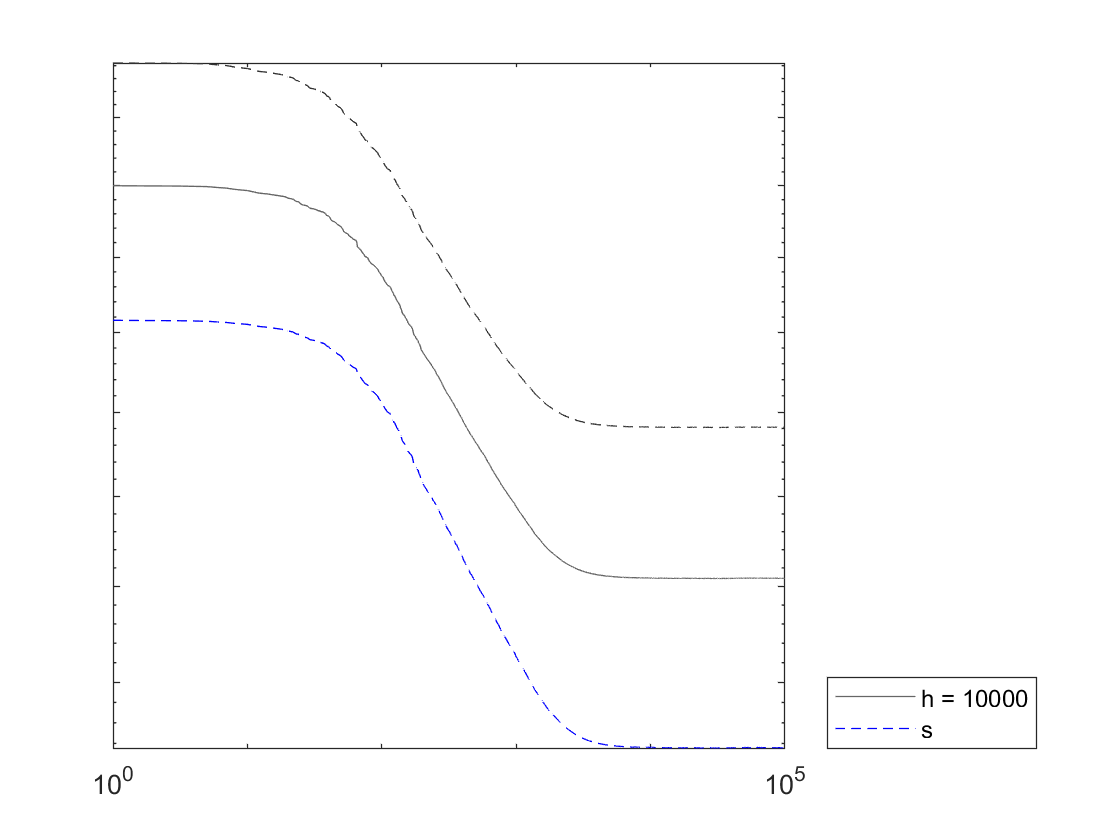

figure
etraj_all = etraj_all(any(etraj_all,2),:);
etraj_avg = mean(etraj_all);
etraj_log_avg = log10(etraj_avg);
etraj_shape = size(etraj_all);
num_trial = etraj_shape(1);
%etraj_err = (0.434*std(etraj_all)./(etraj_log_avg*sqrt(num_trial)))/etraj_avg(1);
etraj_err = (std(etraj_all)./sqrt(num_trial))/etraj_avg(1);
etraj_avg_norm = etraj_avg/etraj_avg(1);
upb = etraj_avg_norm+etraj_err;
lowb = etraj_avg_norm-etraj_err;
%subplot(length(h_M),1,k)
loglog(upb, '--','Color', [1/5,0+1/5,0+1/5]);
hold on
p = zeros(1,2);
p(2) = loglog(lowb, '--','Color', 'b');
hold on
p(1) = loglog(etraj_avg_norm, 'Color', [0+2/5,0+2/5,0+2/5]);
%ylabel('h = '+string(h))
set(gca,'YTickLabel',[]);
legend([p(1) p(2)],'h = '+string(h),'s','Location', 'southeastoutside')